This script is to analyze the autofluorescence in FLP experiments.

The data is collected on Feb 08, 2022, from mouse PM13_noEP.

The mouse was recorded for 20 minutes with head fixed, with 0.04 uW laser power (voltage=4, ND filter adjusted).

FLPfile='continuous aquistion data_7';
timebin=1;
ch=1;




% first load FLIM file 007 to do the fitting.

load(FLPfile);
filename='PM13_autofluo_20220208.mat';

FLiPAnalysis_Tau_p1_Photon(FLPdata_time, FLPdata_lifetimes, timebin,ch, filename);
load(filename)

time(isnan(time))=[];
photoncount(isnan(photoncount))=[];
tau_avg(isnan(tau_avg))=[];
tau_avgTrunc(isnan(tau_avgTrunc))=[];
tau_empTrunc(isnan(tau_empTrunc))=[];
p1(isnan(p1))=[];
chi2(isnan(chi2))=[];
beta2(isnan(beta2))=[];
beta4(isnan(beta4))=[];
beta6(isnan(beta6))=[];
backcorr(isnan(backcorr))=[];

save(filename, 'time','photoncount', 'tau_avg','tau_avgTrunc','tau_empTrunc', 'p1','chi2','beta2','beta4','beta6','backcorr','lifetime_histograms');

PM13_tau_empTrunc=tau_empTrunc;
PM13_photoncount=photoncount;
PM13_tau_avg=tau_avg;
PM13_beta2=beta2;
PM13_beta4=beta4;
PM13_beta6=beta6;
PM13_time=time;
PM13_lifetime_histograms=lifetime_histograms;
PM13_backcorr=backcorr;



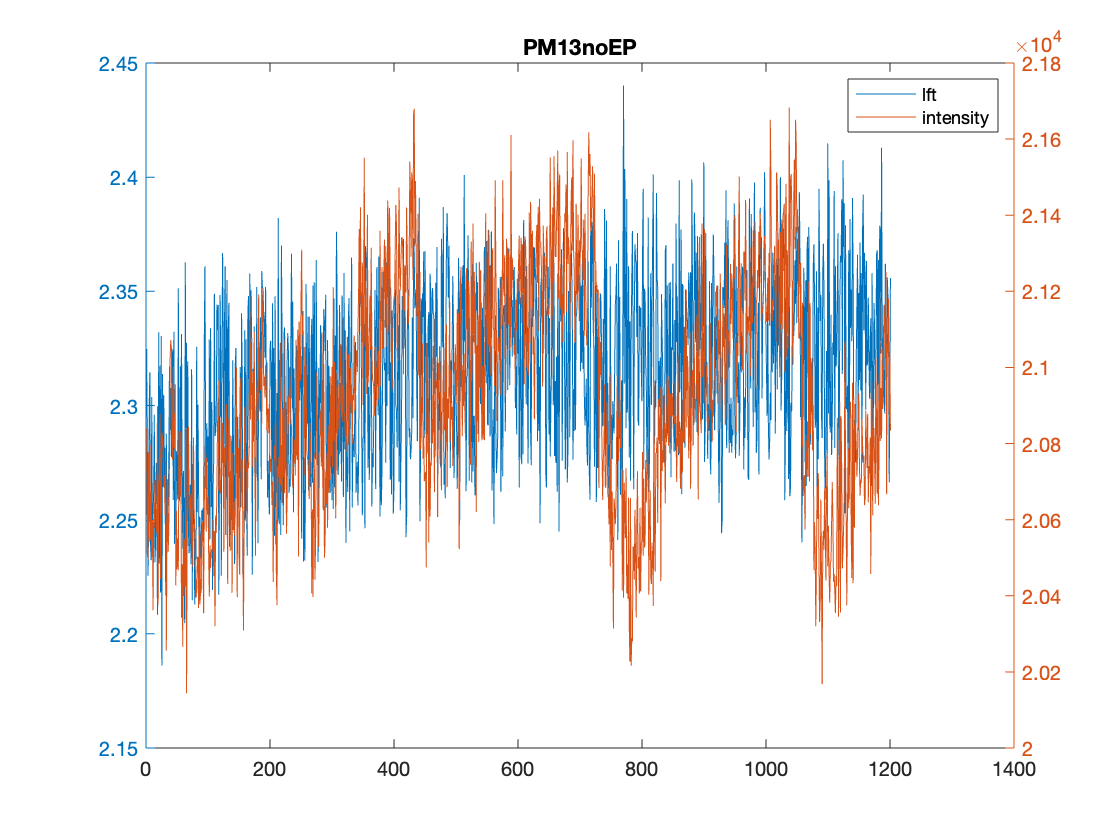

figure
yyaxis left
plot(PM13_time, PM13_tau_empTrunc)
yyaxis right
plot(PM13_time, PM13_photoncount)
title('PM13noEP')
legend('lft','intensity')

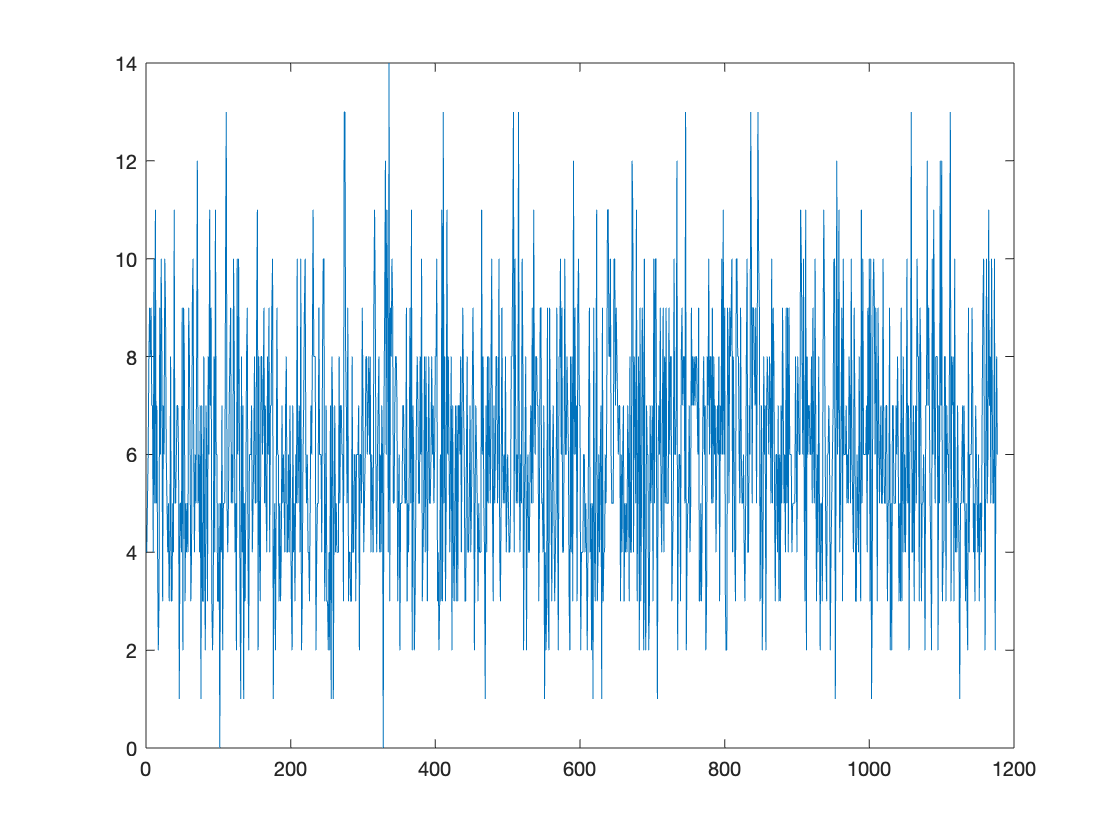


figure
plot(PM13_backcorr)